### Load Stereo Images

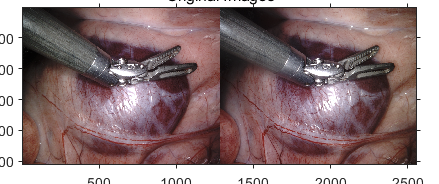

clear all;

% Load the stereo images
I1 = imread('./Stereo Data/left_image.png');
I2 = imread('./Stereo Data/right_image.png');

% Display the images
figure;
imshowpair(I1, I2, 'montage');
title('Original Images');

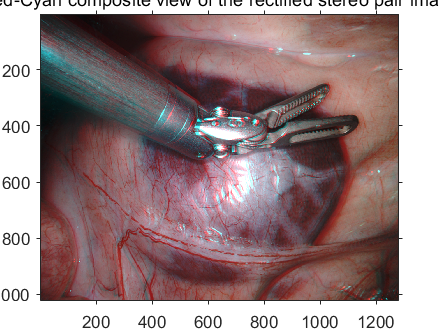


A = stereoAnaglyph(I1,I2);
figure;
imshow(A);
title('Red-Cyan composite view of the rectified stereo pair image');

### Step a:

Detect salient features and plot the detected features on the provided pair of frames.

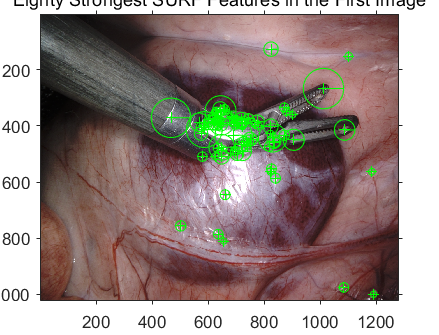

% Convert images to grayscale
I1gray = im2gray(I1);
I2gray = im2gray(I2);

% Detect SURF features with a specified metric threshold
blobs1 = detectSURFFeatures(I1gray, 'MetricThreshold', 1000);
blobs2 = detectSURFFeatures(I2gray, 'MetricThreshold', 1000);

% Plot strongest features for the first image
figure;
imshow(I1);
hold on;
plot(selectStrongest(blobs1, 80), 'showOrientation', true);
title("Eighty Strongest SURF Features in the First Image");
hold off;

frame = getframe(gca);

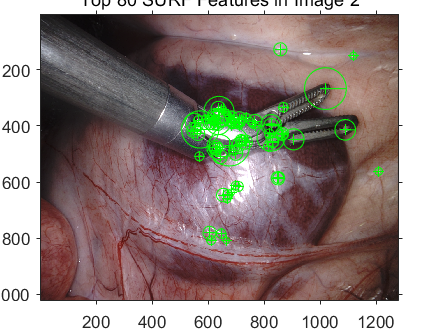

imgWithFeatures1 = frame.cdata;

% Plot strongest features for the second image
figure;
imshow(I2);
hold on;
plot(selectStrongest(blobs2, 80), 'showOrientation', true);
title("Top 80 SURF Features in Image 2");
hold off;

frame = getframe(gca);

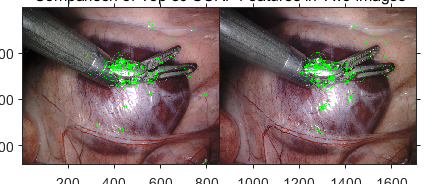

imgWithFeatures2 = frame.cdata;

% Display both images side by side
figure;
imshowpair(imgWithFeatures1, imgWithFeatures2, 'montage');
title('Comparison of Top 80 SURF Features in Two Images');

### Step b:

Find  corresponding  features  between  the  two  frames. Create  a  composite  image  (e.g. centred overlay image) from the two frames and demonstrate the matched points.

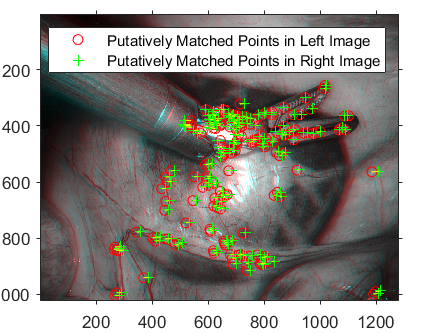

% Extract features and descriptors from grayscale images
[features1, validBlobs1] = extractFeatures(I1gray, blobs1);
[features2, validBlobs2] = extractFeatures(I2gray, blobs2);

% Match features between the two images using SAD metric
indexPairs = matchFeatures(features1, features2, 'Metric', 'SAD', 'MatchThreshold', 5);
matchedPoints1 = validBlobs1(indexPairs(:,1), :);
matchedPoints2 = validBlobs2(indexPairs(:,2), :);

% Display matched features in overlay mode
figure; 
showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2);
legend("Putatively Matched Points in Left Image", "Putatively Matched Points in Right Image");

### Step c:

Use the matched features to estimate the fundamental matrix between the two images.

% Estimate the fundamental matrix from matched points using RANSAC
[fMatrix, epipolarInliers, status] = estimateFundamentalMatrix(...
    matchedPoints1, matchedPoints2, ...
    'Method', 'RANSAC', ...
    'NumTrials', 10000, ...
    'DistanceThreshold', 0.1, ...
    'Confidence', 99.99);

% Display the estimated fundamental matrix in long format scientific notation
disp('Estimated Fundamental Matrix:');

Estimated Fundamental Matrix:


format long e;
disp(fMatrix);

     2.305289119843084e-07    -1.571080458849053e-04     7.846682373730429e-02
     1.569338256670464e-04     3.336165661562943e-06    -5.122062799729321e-01
    -7.911838533790699e-02     5.090023037111786e-01     7.330713772026651e-01




% Check for errors in fundamental matrix estimation
if status ~= 0 || isEpipoleInImage(fMatrix, size(I1)) ...
   || isEpipoleInImage(fMatrix', size(I2))
    error(['Not enough matching points were found or '...
           'the epipoles are inside the images. Inspect '...
           'and improve the quality of detected features '...
           'and images.']);
end

### Step d:

Find the correctly matched points that meet the epipolar constraint.

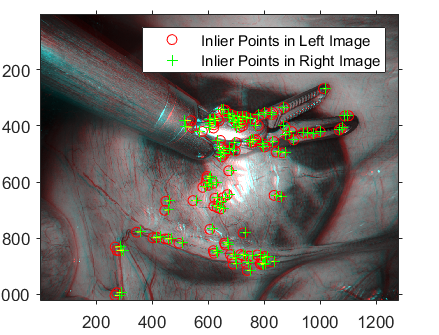

% Extract inlier points based on epipolar inliers
inlierPoints1 = matchedPoints1(epipolarInliers, :);
inlierPoints2 = matchedPoints2(epipolarInliers, :);

% Display matched features
figure;
showMatchedFeatures(I1, I2, inlierPoints1, inlierPoints2);
legend("Inlier Points in Left Image", "Inlier Points in Right Image");

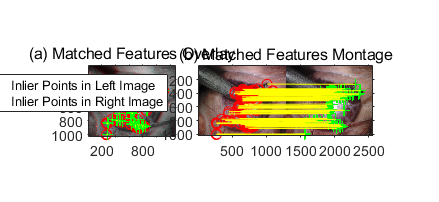


figure;
set(gcf, 'Position', [100, 100, 1300, 600]);

% Subplot 1: Matched features in overlay mode
ax1 = subplot(1, 2, 1);
showMatchedFeatures(I1, I2, inlierPoints1, inlierPoints2);
legend("Inlier Points in Left Image", "Inlier Points in Right Image");
title('(a) Matched Features Overlay');
set(ax1, 'Position', [0.2, 0.3, 0.2, 0.4]);

% Subplot 2: Matched features in montage mode
ax2 = subplot(1, 2, 2);
showMatchedFeatures(I1, I2, inlierPoints1, inlierPoints2, 'montage');
title('(b) Matched Features Montage');
set(ax2, 'Position', [0.45, 0.1, 0.4, 0.8]);

### Step e:

Estimate the diameter of the shaft of the tool shown in the stereo  images. (hint: you can establish the disparity map between the left and right camera images or you can apply 3D surface reconstruction)

% Camera 1
intrinsicMatrix1 = [1.02408777e+03, 0, 6.01806702e+02;
                    0, 1.02389478e+03, 5.08131683e+02;
                    0, 0, 1]';
radialDistortion1 = [-2.52257544e-03, 4.38565714e-03, 9.21500759e-05];
tangentialDistortion1 = [0, 0]';

% Camera 2
intrinsicMatrix2 = [1.02419836e+03, 0, 6.96750427e+02;
                    0, 1.02398749e+03, 5.07494263e+02;
                    0, 0, 1]';
radialDistortion2 = [-3.26306466e-03, 5.70008671e-03, 7.57322850e-05];
tangentialDistortion2 = [0, 0]';

% Create cameraParameters objects
cameraParams1 = cameraParameters('IntrinsicMatrix',intrinsicMatrix1,'RadialDistortion',radialDistortion1);
cameraParams2 = cameraParameters('IntrinsicMatrix',intrinsicMatrix2,'RadialDistortion',radialDistortion2);

% Rotation and translation matrix
R = [9.99999404e-01, -1.24090354e-06, -1.11142127e-03;
     1.29263049e-06, 1.00000000, 4.65405355e-05;
     1.11142127e-03, -4.65419434e-05, 9.99999404e-01];
T = [-4.34818459e+00; 2.83603016e-02; -9.00963729e-04];

% Create stereoParameters object
stereoParams = stereoParameters(cameraParams1,cameraParams2,R,T);

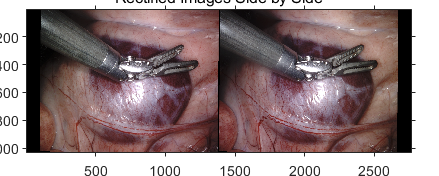

% Rectify stereo images to align them for disparity calculation
[I1_rectified, I2_rectified, reprojectionMatrix] = rectifyStereoImages(I1, I2, stereoParams, 'OutputView', 'full');

% Display the rectified images side by side
figure;
imshowpair(I1_rectified, I2_rectified, 'montage');
title('Rectified Images Side by Side');

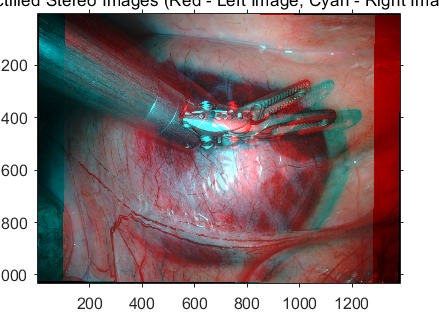


% Display a stereo anaglyph to assess rectification quality
figure;
imshow(stereoAnaglyph(I1_rectified, I2_rectified));
title("Rectified Stereo Images (Red - Left Image, Cyan - Right Image)");

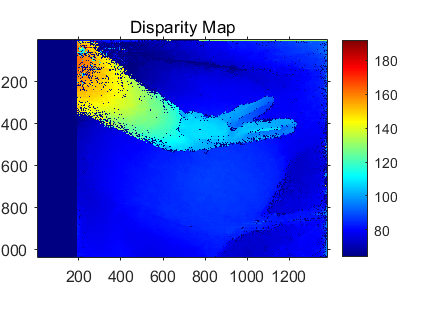

% Convert rectified images to grayscale for disparity analysis
J1_rectified = rgb2gray(I1_rectified);
J2_rectified = rgb2gray(I2_rectified);

% Compute disparity map using Semi-Global Matching
disparityRange = [64 192];
disparityMap = disparitySGM(J1_rectified, J2_rectified, 'DisparityRange', disparityRange, 'UniquenessThreshold', 5);
figure;
imshow(disparityMap, disparityRange);
title('Disparity Map');
colormap jet;
colorbar;
axis image;

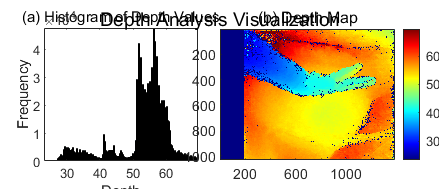

% Reconstruct 3D scene from the disparity map
points3D = reconstructScene(disparityMap, reprojectionMatrix);
X = points3D(:,:,1);
Y = points3D(:,:,2);
Z = points3D(:,:,3);

% Create a figure to hold both subplots
figure;

% Subplot 1: Histogram of depth values
ax1 = subplot(1, 2, 1);
histogram(Z);
title('(a) Histogram of Depth Values');
xlabel('Depth');
ylabel('Frequency');
axis tight;

% Subplot 2: Visualization of the depth map
ax2 = subplot(1, 2, 2);
imagesc(Z);
title('(b) Depth Map');
colormap(ax2, jet);
colorbar;
axis image;

set(ax1, 'Position', [0.1, 0.15, 0.35, 0.7]);
set(ax2, 'Position', [0.5, 0.1, 0.4, 0.8]);

% Adjust overall figure properties
sgtitle('Depth Analysis Visualization');
set(gcf, 'Position', [100, 100, 1400, 600]);

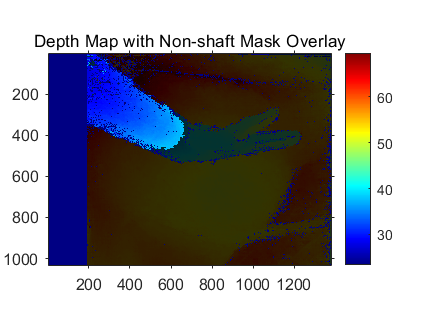

% Extract the focal lengths from the camera's intrinsic matrices
fx = cameraParams1.IntrinsicMatrix(1,1);
fy = cameraParams1.IntrinsicMatrix(2,2);
f = (fx + fy) / 2;

% Segment the depth map to isolate the shaft based on empirical depth thresholds
shaftMask = (Z > 27) & (Z < 38);

% Identify the largest connected component in the segmented image, assumed to be the shaft
shaftRegion = bwlabel(shaftMask);
stats = regionprops(shaftRegion, 'Area', 'PixelIdxList');
[~, maxIdx] = max([stats.Area]);
shaftMask = ismember(shaftRegion, maxIdx);

% Create an inverse mask to display the remaining areas
inverseShaftMask = ~shaftMask & any(Z > 0, 3);

% Display the original rectified image with an overlay of the shaft segmentation
figure;
imagesc(Z);
colormap(gca, jet);
colorbar;
axis image;
hold on;
title('Depth Map with Non-shaft Mask Overlay');

% Create an RGB representation of the shaft mask where the shaft is highlighted
shaftMaskRGB = cat(3, zeros(size(shaftMask)), ones(size(shaftMask)), zeros(size(shaftMask)));
inverseMaskRGB = cat(3, zeros(size(inverseShaftMask)), zeros(size(inverseShaftMask)), zeros(size(inverseShaftMask)));

% % Show the RGB overlay of the shaft mask
% h = imshow(shaftMaskRGB);
% set(h, 'AlphaData', 0.8 * shaftMask);

% Show the RGB overlay of the inverse mask to highlight remaining areas
h2 = imshow(inverseMaskRGB);
set(h2, 'AlphaData', 0.8 * inverseShaftMask);

hold off;

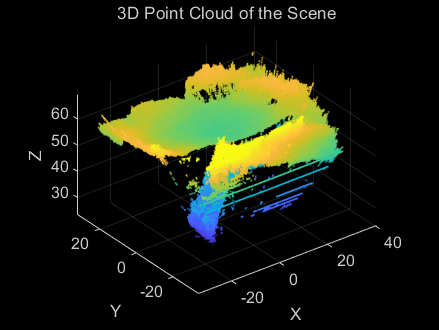

% Combine X, Y, and Z matrices into a single matrix for point cloud creation
ptCloud = pointCloud(cat(3, X, Y, Z));

% Display the point cloud using the pcshow function
figure;
pcshow(ptCloud);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Point Cloud of the Scene');
view(3);

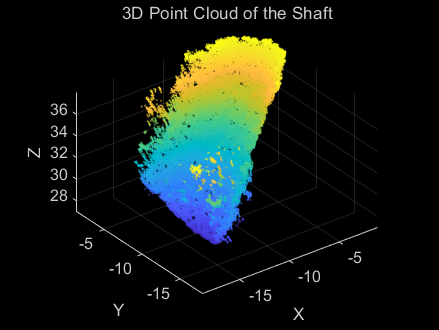

% Apply mask across all dimensions to extract the shaft points
shaftPoints = points3D(repmat(shaftMask, [1, 1, 3]));  
shaftPoints = reshape(shaftPoints, [], 3);  
shaftPoints = shaftPoints(all(~isinf(shaftPoints) & ~isnan(shaftPoints), 2), :);

% Create a point cloud object from the cleaned shaft points
shaftPointCloud = pointCloud(shaftPoints);

figure;
pcshow(shaftPointCloud);
title('3D Point Cloud of the Shaft');
xlabel('X');
ylabel('Y');
zlabel('Z');
axis equal;

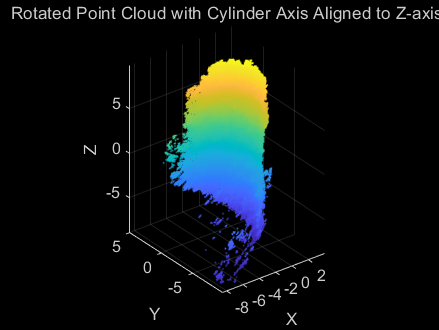

% Calculate PCA to find the principal component (main axis) of the shaft
meanData = mean(shaftPoints, 1);
centeredData = shaftPoints - meanData;
[coeff, ~, ~] = pca(centeredData);

% Construct a rotation matrix to align the cylinder's axis to the Z-axis
cylinderAxis = coeff(:,1);
targetAxis = [0; 0; 1];
rotationAxis = cross(cylinderAxis, targetAxis);
rotationAngle = acos(dot(cylinderAxis, targetAxis) / (norm(cylinderAxis) * norm(targetAxis)));
rotationMatrix = axang2rotm([rotationAxis' rotationAngle]);

% Rotate the point cloud to align it with the Z-axis
rotatedPoints = (rotationMatrix * centeredData')';

% Create and display a point cloud object from the rotated points
rotatedPointCloud = pointCloud(rotatedPoints);
figure;
pcshow(rotatedPointCloud);
title('Rotated Point Cloud with Cylinder Axis Aligned to Z-axis');
xlabel('X');
ylabel('Y');
zlabel('Z');
axis equal;
view(3);

% Extract Z values from the rotated points and determine a median-based range for selection
zValues = rotatedPoints(:,3);
medianZ = median(zValues);
zRange = 10;
selectedPoints = rotatedPoints(zValues > (medianZ - zRange) & zValues < (medianZ + zRange), :);

% Convert selected points to double precision for numerical operations
xData = double(selectedPoints(:,1));
yData = double(selectedPoints(:,2));

% Define initial guesses for the circle fitting [center_x, center_y, radius]
initialGuess = double([mean(xData), mean(yData), range(xData)/2]);

% Setup options for nonlinear least squares fitting
options = optimoptions('lsqnonlin', 'Display', 'iter');

% Fit a circle to the data using nonlinear least squares
fittedParams = lsqnonlin(@(params) circleFitObjective(params, [xData, yData]), ...
                         initialGuess, [], [], options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4     2.07817e+06                      4.57e+05
     1          8           97194        4.35953       7.99e+04      
     2         12         22110.5        2.16941       9.14e+03      
     3         16         19733.1       0.773151            893      
     4         20         19649.7       0.179398           59.8      
     5         24         19647.2      0.0326057           13.9      
     6         28         19647.2     0.00551423           2.45      
     7         32         19647.2    0.000918661           0.41      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the 


% Extract fitted circle parameters
fittedA = fittedParams(1);
fittedB = fittedParams(2);
fittedR = fittedParams(3);

% Output fitted circle information
fprintf('Fitted Circle: Center = (%f, %f), Radius = %f\n', fittedA, fittedB, fittedR);

Fitted Circle: Center = (-3.628971, -2.323381), Radius = 4.921813


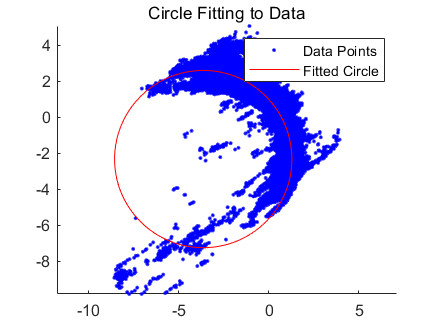


% Visualize fitting results along with the original data points
figure;
scatter(xData, yData, 'b.');
hold on;
theta = linspace(0, 2*pi, 100);
plot(fittedA + fittedR*cos(theta), fittedB + fittedR*sin(theta), 'r-'); % Draw fitted circle
axis equal;
title('Circle Fitting to Data');
legend('Data Points', 'Fitted Circle');

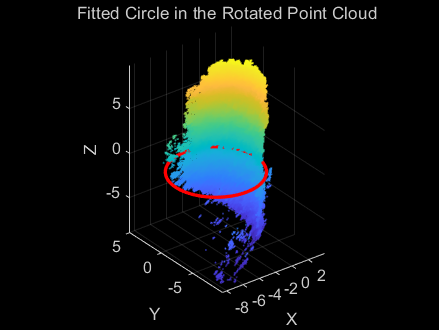


% Compute 3D coordinates for the fitted circle at median Z height
x = fittedA + fittedR * cos(theta);
y = fittedB + fittedR * sin(theta);
z = medianZ * ones(size(x));

% Reshape and prepare for 3D plotting
rotatedCirclePoints = [x; y; z];

% Display the rotated point cloud and overlay the fitted circle
figure;
pcshow(rotatedPointCloud);
hold on;
plot3(rotatedCirclePoints(1,:), rotatedCirclePoints(2,:), rotatedCirclePoints(3,:), 'r-', 'LineWidth', 2);
title('Fitted Circle in the Rotated Point Cloud');
xlabel('X');
ylabel('Y');
zlabel('Z');
axis equal;
view(3);
hold off;

% Calculate residuals for fitted circle
residuals = sqrt((xData - fittedA).^2 + (yData - fittedB).^2) - fittedR;

% Compute standard deviation of residuals for error estimation
sigma_R = std(residuals);
sigma_D = 2 * sigma_R;

% Compute diameter from fitted radius
diameter = 2 * fittedR;
diameterErrorRange = [diameter - sigma_D, diameter + sigma_D];

% Output estimated diameter and error range
fprintf('Estimated Diameter: %f mm\n', diameter);

Estimated Diameter: 9.843625 mm


fprintf('Diameter Error Range: [%f, %f] mm\n', diameterErrorRange(1), diameterErrorRange(2));

Diameter Error Range: [8.996242, 10.691009] mm


function D = circleFitObjective(params, data)
    a = params(1);
    b = params(2);
    r = params(3);
    distances = sqrt((data(:,1) - a).^2 + (data(:,2) - b).^2);
    D = distances - r;
end